mycobot = importrobot("/home/anirudh/Desktop/ASU/Robotics/Lab4/mycobot_pro_600/mycobot_pro_600.urdf")

mycobot =   rigidBodyTree with properties:

     NumBodies: 6
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link1'  'link2'  'link3'  'link4'  'link5'  'link6'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


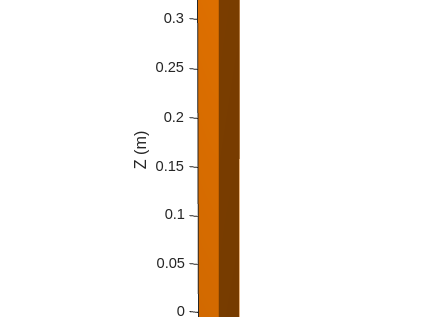

%Camera stand vertical
width = 0.03;  
len = 0.03; 
height = 0.37; 


collisionBoxObj = collisionBox(width, len, height);

position = [-0.49, -0.282, 0.165]; 


collisionBoxObj.Pose = trvec2tform(position);


show(collisionBoxObj);
axis equal;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Collision Box in Robot Workspace');

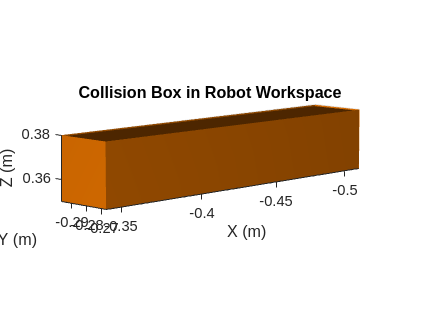

%Camera stand horizontal
width = 0.17;  
len = 0.03; 
height = 0.03; 


collisionBoxObj_2 = collisionBox(width, len, height);


%position = [-0.392, -0.269, 0.365]; 
position = [-0.426, -0.282, 0.365]; 

collisionBoxObj_2.Pose = trvec2tform(position);


show(collisionBoxObj_2);
axis equal;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Collision Box in Robot Workspace');

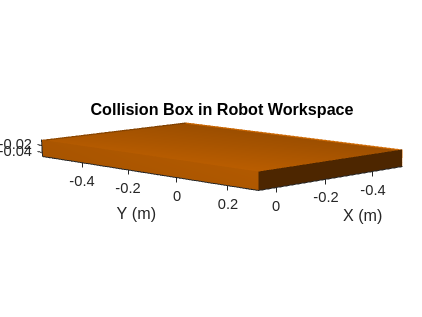

%Table
width = 0.6;  
len = 0.9; 
height = 0.05; 


collisionBoxObj_3 = collisionBox(width, len, height);


position = [-0.46314/2, -0.269/2, -0.028]; 


collisionBoxObj_3.Pose = trvec2tform(position);


show(collisionBoxObj_3);
axis equal;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Collision Box in Robot Workspace');

%Aruco targets collision avoidance
startConfigStruct = homeConfiguration(mycobot);
env = {collisionBoxObj, collisionBoxObj_2, collisionBoxObj_3}

env = 1×3 cell array
    {1×1 collisionBox}    {1×1 collisionBox}    {1×1 collisionBox}


robot_coords = pyrunfile("/home/anirudh/Desktop/ASU/Robotics/Lab4/robot_coords_2.py", "robot_coords")

[ WARN:0@428.441] global cap_v4l.cpp:982 open VIDEOIO(V4L2:/dev/video2): can't open camera by index
[ERROR:0@428.539] global obsensor_uvc_stream_channel.cpp:156 getStreamChannelGroup Camera index out of range


robot_coords =   Python ndarray:

 -387.1248 -334.7487    1.0000
 -293.3031 -229.3897    1.0000

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


coordsArray = 0.001*double(robot_coords);
coordsArray(:, 3) = 0.1;
target1 = trvec2tform(coordsArray(1, :));
target2 = trvec2tform(coordsArray(2, :));

[path_, solInfo, configSol, path2, solInfo2, configSol2] = coordinate2_path(mycobot, target1, target2, env, startConfigStruct)

Found a collision-free path!


Found a collision-free path!


path_ =          0   -2.3562         0         0    1.6581         0
    0.2079   -2.2718   -0.3262   -0.0370    1.6910   -0.0275
    0.2327   -2.2582   -0.5502   -0.0363    1.5456   -0.3240
    0.1992   -2.1380   -0.7178    0.0340    1.7627   -0.5775
    0.3857   -2.2318   -0.8997    0.1353    1.8705   -0.8254
    0.4662   -2.3502   -1.0377    0.0138    1.9497   -1.1407
    0.4851   -2.3375   -1.2644   -0.1996    1.8570   -1.3729
    0.9364   -2.5112   -1.6698   -1.0086    1.8253   -1.4420
    0.9496   -2.4789   -1.3367   -1.1047    1.6715   -1.5643
    0.9209   -2.5036   -1.1542   -0.9979    1.6078   -1.8956


solInfo = struct with fields:
           Iterations: 35
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9836e-08
             ExitFlag: 1
               Status: 'success'


configSol = 1×6 struct array with fields:
    JointName
    JointPosition


path2 =     0.9278   -2.5340   -1.3348   -0.8436    1.5708   -2.2138
    0.9757   -2.5723   -1.4452   -0.6421    1.5635   -1.8923
    0.9611   -2.1868   -2.0985   -0.4272    1.5708   -2.1805


solInfo2 = struct with fields:
           Iterations: 38
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1082e-08
             ExitFlag: 1
               Status: 'success'


configSol2 = 1×6 struct array with fields:
    JointName
    JointPosition


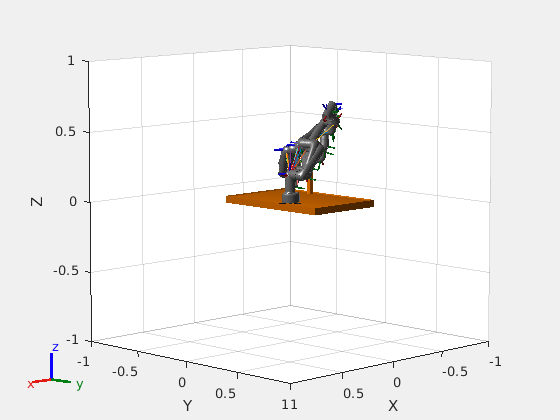

path1_len = 8

waypoints1 =          0   -2.3562         0         0    1.6581         0
    0.2203   -2.2650   -0.4382   -0.0367    1.6183   -0.1758
    0.1992   -2.1380   -0.7178    0.0340    1.7627   -0.5775
    0.4259   -2.2910   -0.9687    0.0745    1.9101   -0.9830
    0.4851   -2.3375   -1.2644   -0.1996    1.8570   -1.3729
    0.7483   -2.4388   -1.5008   -0.6714    1.8385   -1.4132
    0.9423   -2.4967   -1.5199   -1.0518    1.7561   -1.4970
    0.9223   -2.5023   -1.1633   -1.0033    1.6110   -1.8791


[path1_len,waypoints1] = display_path(mycobot,path_,env,startConfigStruct)

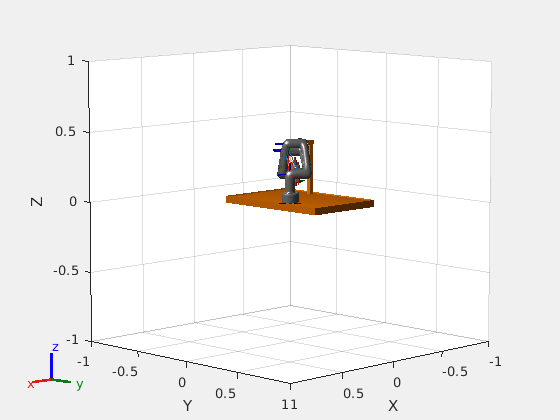

path2_len = 3

waypoints2 =     0.9278   -2.5340   -1.3348   -0.8436    1.5708   -2.2138
    0.9722   -2.4804   -1.6008   -0.5909    1.5653   -1.9609
    0.9618   -2.2049   -2.0677   -0.4373    1.5705   -2.1669


[path2_len,waypoints2] = display_path(mycobot,path2,env,configSol)

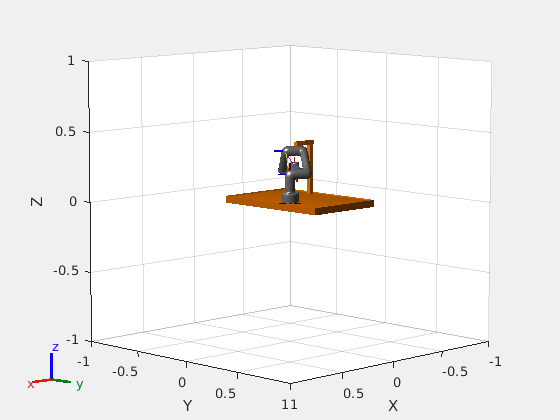

display_robot(mycobot,path2,env,configSol)

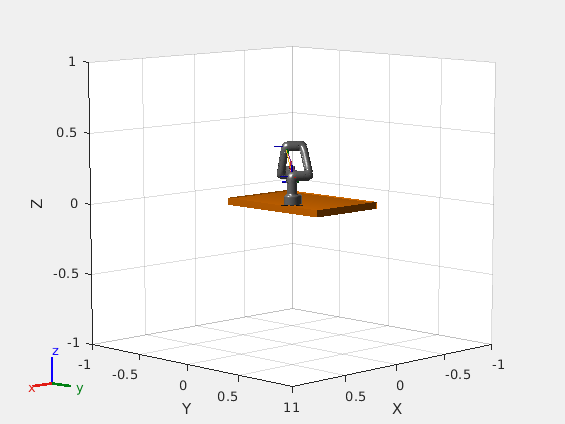

display_robot(mycobot,path2,env,configSol2)

robot_control(waypoints1)

Connected to 192.168.1.159:5001
Sent: set_angles(0,-135,0,0,0,0,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(4,-134,-7,-15,-11,11,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(9,-135,-16,-19,1,-6,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(14,-136,-24,-22,13,-23,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(19,-137,-33,-26,24,-39,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(24,-138,-42,-29,36,-56,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(29,-139,-50,-33,48,-73,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(34,-140,-59,-36,59,-89,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent:

robot_control(waypoints2)

Connected to 192.168.1.159:5001
Sent: set_angles(53,-145,-78,-48,90,-127,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(45,-136,-79,-48,73,-117,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(46,-138,-76,-63,61,-105,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(46,-140,-74,-77,49,-92,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(47,-142,-71,-92,37,-79,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(47,-144,-68,-107,25,-67,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(48,-146,-66,-121,13,-54,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(49,-148,-63,-136,1,-42,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.16

% robot_control([25,-142,-76,-59,90,33]);

% robot_coords = pyrunfile("/home/anirudh/Desktop/ASU/Robotics/Lab4/robot_coords_2.py", "robot_coords")

Connected to 192.168.1.159:5001
Sent: set_angles(1432,-8136,-4354,-3380,5157,1891,500)
Received: set_angles:[invalid angles]
Connection closed.


% coordsArray = 0.001*double(robot_coords);
% coordsArray(:, 3) = 0.1;

(array([[[260., 438.],
        [248., 392.],
        [294., 380.],
        [306., 426.]]], dtype=float32), array([[[470.,  68.],
        [483., 114.],
        [436., 127.],
        [424.,  81.]]], dtype=float32))


robot_coords =   Python ndarray:

 -397.2901 -249.9216    1.0000
 -280.4606 -328.2771    1.0000

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


% target1 = trvec2tform(coordsArray(1, :));
% target2 = trvec2tform(coordsArray(2, :));
% 
% [configSol, solInfo] = inverse_k(mycobot, target1);
% jp1 = [configSol.JointPosition];
% [configSol2, solInfo2] = inverse_k(mycobot, target2);
% jp2 = [configSol2.JointPosition];
% js=  [jp1;jp2];
% %robot_control(js);

% target2

% bleh = deg2rad([53,-142,-76,-59,90,33]);
% bleh

% robot_control(js);

target2 =     1.0000         0         0   -0.2863
         0    1.0000         0   -0.3317
         0         0    1.0000    0.1000
         0         0         0    1.0000


function [path, solInfo, configSol, path2, solInfo2, configSol2] = coordinate2_path(mycobot, target1, target2, env, startConfigStruct)
    [path, solInfo, configSol] = findCollisionFreePath(mycobot, target1, env, startConfigStruct);

bleh =     0.9250   -2.4784   -1.3265   -1.0297    1.5708    0.5760


    [path2, solInfo2, configSol2] = findCollisionFreePath(mycobot, target2, env, configSol);
end

Connected to 192.168.1.159:5001
Sent: set_angles(46,-138,-91,-40,90,-134,500)
Received: set_angles:[ok]
Connection closed.
Connected to 192.168.1.159:5001
Sent: set_angles(64,-133,-103,-34,90,-116,500)
Received: set_angles:[ok]
Connection closed.


function [path, solInfo, configSol] = findCollisionFreePath(mycobot, targetPosition, env, startConfigStruct)

    mycobot.DataFormat = 'struct';
    startConfig = [startConfigStruct.JointPosition];
    [configSol, solInfo] = inverse_k(mycobot, targetPosition);


    if solInfo.Status == "success" || solInfo.Status == "best available"

        targetConfig = [configSol.JointPosition];


        mycobot.DataFormat = 'row';
        planner = manipulatorRRT(mycobot, env);
        planner.SkippedSelfCollisions = "parent";
        planner.MaxConnectionDistance = 0.4;
        planner.ValidationDistance = 0.05;

        inCollision = false;
        for j = 1:length(env)
            % Check collision for each obstacle in the environment
            if checkCollision(mycobot, targetConfig, {env{j}})
                disp("Configuration is in collision with environment.");
                inCollision = true;
                mycobot.DataFormat = 'row';
                break;
            end
        end

        if ~inCollision
            try
                path = planner.plan(startConfig, targetConfig);
                if ~isempty(path)
                    disp("Found a collision-free path!");
                    mycobot.DataFormat = 'struct'; 
                    return; 
                end
            catch %Collision occurs in the path
                disp("Failed to find a path for this IK solution.");
            end
        else %Inverse Kinematics solution collides
            disp("No valid path found due to collision.");
        end

        mycobot.DataFormat = 'struct';
    else %No inverse kinematics solution exists
        error('Inverse kinematics did not return a valid solution.');
    end

    path = [];
end   


function [path_len, storedPath] = display_path(mycobot, path, env, startConfigStruct)

    ax = show(mycobot, startConfigStruct, 'PreservePlot', false);
    hold on;
    mycobot.DataFormat = 'row';
    path_len = 0;

    rrt = manipulatorRRT(mycobot, env);
    rrt.SkippedSelfCollisions = "parent";
    interpPath = interpolate(rrt, path);
    for i = 1:length(env)
        show(env{i}, 'Parent', ax);
    end
    storedPath = [];
    for i = 1:60:size(interpPath, 1)
        show(mycobot, interpPath(i, :), 'Parent', ax);
        storedPath = [storedPath; interpPath(i, :)];
        path_len=path_len+1;
    end

    mycobot.DataFormat = 'struct';
    
    hold off;
end

function [configSol, solInfo] = inverse_k(robot_2, position)
    eulerAngles = [90, 0, 90];
    eulerAnglesRad = deg2rad(eulerAngles);
    
    rotationMatrix = eul2tform(eulerAnglesRad, 'XYZ'); 
    
    endEffectorPose = position * rotationMatrix;

    ik = inverseKinematics('RigidBodyTree', robot_2);
    
    
    weights = [1, 1, 1, 0.2, 0.2, 0.2];
    initialguess = robot_2.homeConfiguration;
    ee = robot_2.BodyNames{end};      
    [configSol, solInfo] = ik(ee, endEffectorPose, weights, initialguess);
end

function display_robot(mycobot, path, env, startConfigStruct)

    ax = show(mycobot, startConfigStruct, 'PreservePlot', false);
    hold on;

    for i = 1:length(env)
        show(env{i}, 'Parent', ax);
    end
    
    hold off;
end

function send_tcp_packet(server_ip, server_port, message)
    try
        % Create a TCP client
        t = tcpclient(server_ip, server_port, 'Timeout', 10);
        disp(['Connected to ', server_ip, ':', num2str(server_port)]);
        
        % Send the message
        write(t, uint8(message));  % Convert message to uint8 for transmission
        disp(['Sent: ', message]);

        % Optionally receive a response from the server
        pause(0.5); % Allow some time for response (if necessary)
        if t.BytesAvailable > 0
            response = read(t, t.BytesAvailable, 'char');
            disp(['Received: ', response]);
        end

    catch ME
        % Display any errors
        disp(['Error: ', ME.message]);
    end

    % Ensure the connection is closed
    clear t;
    disp('Connection closed.');
end

function robot_control(path)
    server_ip = '192.168.1.159';
    server_port = 5001;
    for i = 1:size(path, 1)
    angleStr = sprintf('%s,%d', strjoin(string(int32(rad2deg(path(i, :)))), ','), int32(500));

    send_angles_command = sprintf('set_angles(%s)', angleStr);

    %disp(send_angles_command);
    send_tcp_packet(server_ip, server_port, send_angles_command)
    end
end